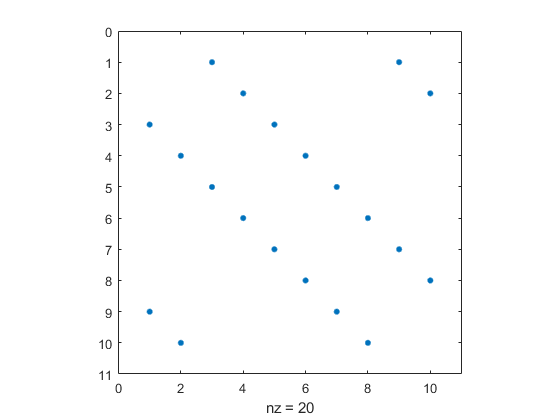

figure(1);
FiniteDiffMatrix([1 1], [2, -2], 10);

### Finite Difference Operators. 

We are interested in the 2d scenario, and we want the second order, second derivative, periodic boundary condition, on both the x, y, and the Laplacian operator on a 4 by 4 grid. 

Discretizastion: columns, the same x value are going to pack into the vector first. 

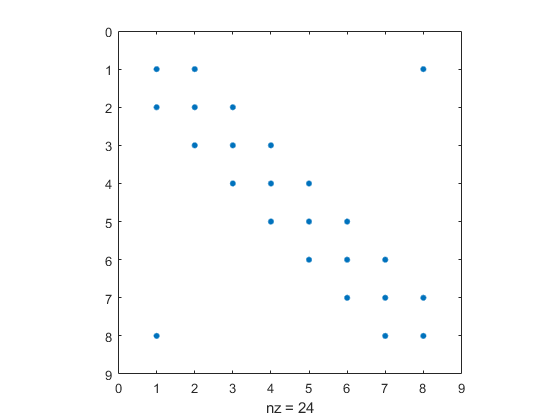

PartialXX = FiniteDiffMatrix([1 -2 1], [-1, 0, 1], 8);
PartialYY = PartialXX;
figure(2); 
spy(PartialXX); 

#### The Laplacian

Let's use tensor product to get the Laplacian operator working here. 

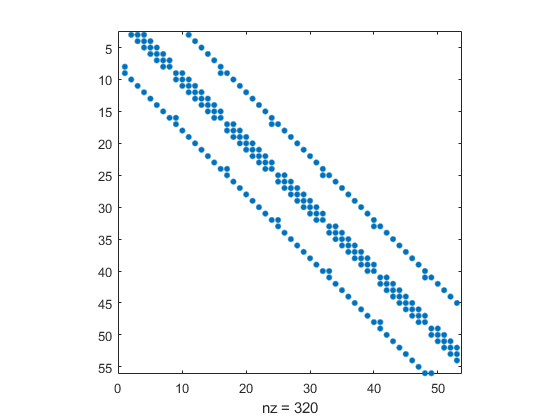

Laplacian = kron(eye(8), PartialXX) + kron(PartialYY, eye(8));
spy(Laplacian)